# Summary Results Demo

Use `SummaryResults` function to compare the costs values for the diferent states of the plant

#### Select and read the data model file

filename="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(filename);

#### Select the parameters

param=struct();
if data.isResourceCost
    Samples=convertCharsToStrings(data.SampleNames);
    param.ResourceSample=convertStringsToChars(Samples(1));
end

#### Get the Summary Results

res=SummaryResults(data,param);
ShowResults(res);

Summary Flows Exergy (kW)

 Key            REF      TRB75     PBLR18      PCND2      noIHE
————————————————————————————————————————————————————————————————
 B1          83.570     89.430     83.930     87.640     83.570
 B2          17.900     19.540     18.460     21.920     17.900
 B3          15.790     16.940     16.390     19.590     17.900
 B4           5.784      6.190      6.011      6.340      5.784
 B5           7.877      8.430      7.948      8.528      7.877
 B6           9.420     10.310      9.471     10.330      7.877
 QBLR       100.000    106.300    100.800    103.500    106.900
 WP           2.447      2.619      2.264      2.554      2.447
 WN          50.000     50.000     50.000     50.000     50.000
 QCND        10.006     10.750     10.379     13.250     12.116


Summary Process Unit Consumption (J/J)

 Key           REF      TRB75     PBLR18      PCND2      noIHE
———————————————————————————————————————————————————————————————
 BLR        1.3486     1.3435     1

#### Show the default summary results graph

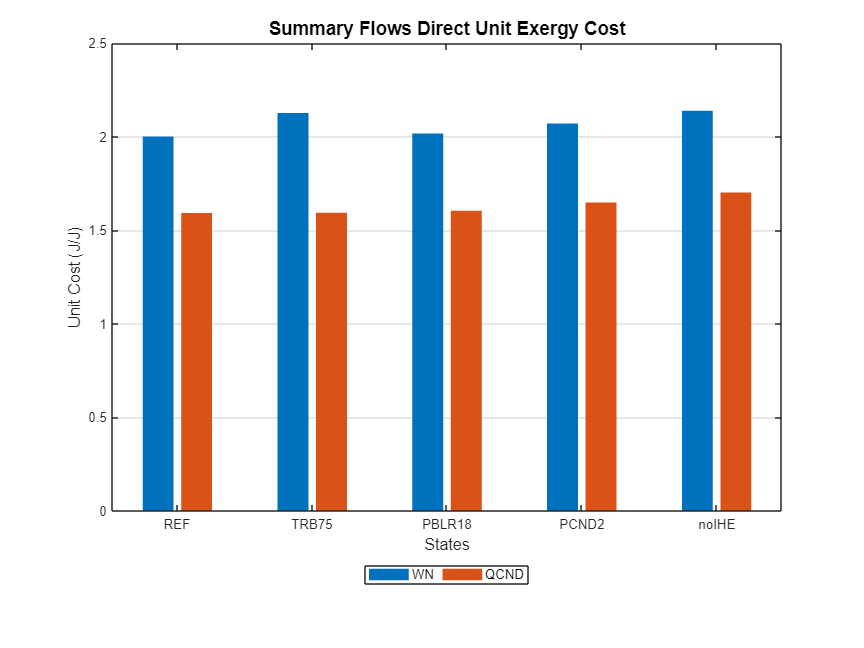

ShowGraph(res);

#### Save the summary results into an excel file

outfile='SummaryResults.xlsx';
SaveOption=true;
if SaveOption
    SaveResults(model,outfile);
end

INFO: cStatusLogger. File SummaryResults.xlsx has been saved
